% Experiment on the Cascaded watertanks benchmark
%
% References
% ---------
%
% A Tensor Network Kalman filter with an application in recursive MIMO Volterra system identification
% 2016, Kim Batselier, Zhongming Chen, Ngai Wong
% 

clear all
close all
clc

%for reproducibility
rng(1);

load('dataBenchmark')


Preprocessing Data

tic

% Normalize the input and output training data to [0 1]
input = uEst/7;
output = yEst/10-0.1;

% plot(input)
% plot(output)
% 
% histogram(input)
% histogram(output)

% Normalize the input and output test data to [0 1]
tinput = uVal/7 ;
toutput = yVal/10-0.1;

% Choose the lags for the input and output
inlags=[1 2];
outlags=[0 1 2 3 4 8 16];
% outlags=[0 1 2 3 4];

inlags=[1 2 3 4 8 16 32];
outlags=[0 1 2 3 4 8 16 32];

inlags=[1:2:31];
outlags=[0 1:2:31];

% ending = 1024-max(outlags(end),inlags(end))-1;

% % generate features using input lags
% for l = 1:length(inlags)
% u(:,l) = input(end-inlags(l)-ending:end-inlags(l));
% uv(:,l) = tinput(end-inlags(l)-ending:end-inlags(l));
% end
% % generate features using output lags
% for l = 1:length(outlags)
% y(:,l) = output(end-outlags(l)-ending:end-outlags(l));
% yv(:,l) = toutput(end-outlags(l)-ending:end-outlags(l));
% end
% 
% 

Split test and training set

% % Features are lagged inputs and outputs
% featurez = [y(:,end:-1:2)  u];
% % Target is output with zero lag
% zeta = y(:,1);
% 
% tfeaturez = [yv(:,end:-1:2)  uv];
% yt = yv(:,1);

[featurez,zeta,tfeaturez,yt] = lagfeatures(input,tinput,output,toutput,inlags,outlags)

featurez =     0.4205    0.4221    0.4200    0.4216    0.4204    0.4207    0.4197    0.4207    0.4254    0.4261    0.4306    0.4338    0.4408    0.4461    0.4484    0.4607    0.4620    0.4719    0.4750    0.4710    0.4612    0.4482    0.4351    0.4251    0.4200    0.4207    0.4264    0.4355    0.4456    0.4548    0.4616    0.4652
    0.4215    0.4214    0.4231    0.4208    0.4218    0.4192    0.4233    0.4236    0.4279    0.4303    0.4334    0.4358    0.4430    0.4486    0.4530    0.4632    0.4550    0.4677    0.4744    0.4739    0.4667    0.4549    0.4415    0.4296    0.4218    0.4196    0.4230    0.4307    0.4406    0.4504    0.4585    0.4638
    0.4221    0.4200    0.4216    0.4204    0.4207    0.4197    0.4207    0.4254    0.4261    0.4306    0.4338    0.4408    0.4461    0.4484    0.4607    0.4678    0.4472    0.4620    0.4719    0.4750    0.4710    0.4612    0.4482    0.4351    0.4251    0.4200    0.4207    0.4264    0.4355    0.4456    0.4548    0.4616
    0.4214    0.4231    0.

zeta =     0.4632
    0.4678
    0.4692
    0.4742
    0.4792
    0.4808
    0.4832
    0.4844
    0.4921
    0.4897


tfeaturez =     0.3973    0.3970    0.3983    0.3971    0.3904    0.3740    0.3574    0.3420    0.3271    0.3123    0.3025    0.2958    0.2920    0.2852    0.2852    0.2849    0.3997    0.4074    0.4125    0.4114    0.4008    0.3788    0.3458    0.3049    0.2614    0.2211    0.1889    0.1672    0.1552    0.1494    0.1453    0.1395
    0.3972    0.3988    0.3968    0.3936    0.3815    0.3667    0.3470    0.3348    0.3198    0.3069    0.2978    0.2911    0.2865    0.2835    0.2818    0.2846    0.3959    0.4036    0.4105    0.4130    0.4075    0.3913    0.3635    0.3260    0.2831    0.2405    0.2038    0.1767    0.1601    0.1518    0.1474    0.1427
    0.3970    0.3983    0.3971    0.3904    0.3740    0.3574    0.3420    0.3271    0.3123    0.3025    0.2958    0.2920    0.2852    0.2852    0.2849    0.2816    0.3925    0.3997    0.4074    0.4125    0.4114    0.4008    0.3788    0.3458    0.3049    0.2614    0.2211    0.1889    0.1672    0.1552    0.1494    0.1453
    0.3988    0.3968    0

yt =     0.2846
    0.2816
    0.2853
    0.2834
    0.2833
    0.2835
    0.2836
    0.2867
    0.2832
    0.2864


Construct B-spline basis vectors


[N, d]=size(featurez); % Number of samples and features

n = 3;                  %Degree B-spline
m = 1;                  %Number of knot intervals
In = n+m;               %Number of B-splines



Initialize tensor train

% Choose TT-ranks
maxrank = 8;

r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));


Cross validation for tuning lambda


LAM = logspace(-4,-10,15);

difforder=2;
MAXITR = 2*d;

tic
for period = 1:numel(LAM)

    lambda = LAM(period);
    
for trial = 1:3
% selc= setdiff(1:length(featurez),(trial-1)*252+1:trial*252);
% selc = randperm(length(featurez),900);

tselc = (1:200)+(trial-1)*200;
selc = setdiff(1:length(featurez),tselc);

fold = featurez(selc,:);
tfold = featurez(tselc,:);

Nf= size(fold, 1);

unf = basisvectors(fold,n,m);

for initial = 1:1
[TNf,Vmf,Vpf] = initTT(unf,r,d);

[TN,~,~,~,~] = optimTT(TNf,Vmf,Vpf,unf,zeta(selc),MAXITR,[],lambda,difforder);
% [simoutput] = simnarx(TN,tinput,toutput,inlags,outlags,n,m);
% RMSE_S(period,trial,initial) = sqrt(immse(10*toutput,10*simoutput));

yhat = evalspline(TN,tfold,n,m);
RMSE_P(period,trial,initial) = sqrt(immse(10*yhat,10*zeta(tselc)));
end
end
% figure
% hold on
% plot(10*toutput+1,'linewidth',2)
% plot(10*simoutput+1,'linewidth',2)
% hold off

% figure
% hold on
% plot(10*yt+1,'linewidth',2)
% plot(10*yhat+1,'linewidth',2)
%  hold off

end
toc

Elapsed time is 28.452697 seconds.


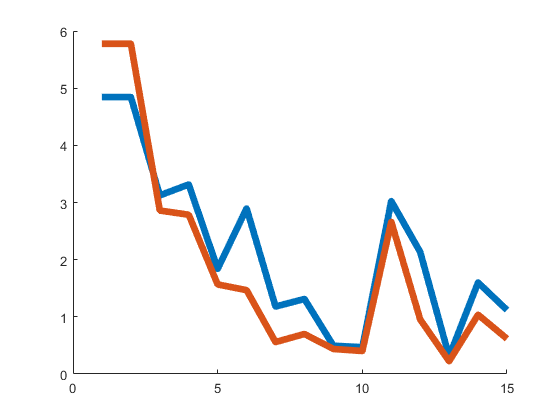


figure
hold on
% plot(RMSE_P)
% plot(RMSE_S)
plot(squeeze(mean(RMSE_P,2)),"LineWidth",5)
plot(squeeze(median(RMSE_P,2)),"LineWidth",5)
% plot(mean(RMSE_S,2),"LineWidth",5)
hold off


% scatter(mean(RMSE_P,2),mean(RMSE_S,2))
% scatter(median(RMSE_P,2),median(RMSE_S,2))

% [~,hyp] = min(median(median(RMSE_P,2),3));
[~,hyp] = min(mean(mean(RMSE_P,2),3));
lambda = LAM(hyp)

lambda = 7.1969e-10



% Construct the basis vectors from the features
un = basisvectors(featurez,n,m);

% Initialize Tensor Train and Vp and Vm
[TN,Vm,Vp] = initTT(un,r,d);


Optimize TT cores


lambda = 4.6416e-07 %from cross val

lambda = 4.6416e-07

difforder=1;
MAXITR = 2*d;


tic
[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,[],lambda,difforder);
toc

Elapsed time is 28.473875 seconds.


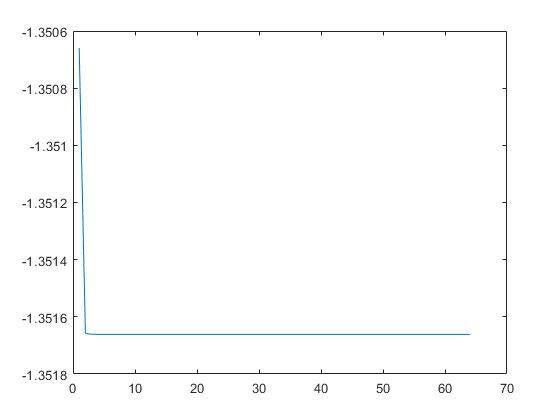

plot(log(res1))

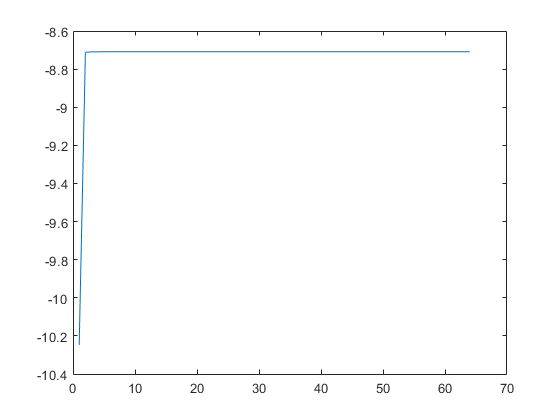

plot(log(res2))

Prediction Train data

% trainerror = res1(end)
% 
% yhattrain  = evalspline(TN,featurez,n,m);
% 
% figure;
% hold on
% plot(zeta)
% plot(yhattrain)
% hold off
% axis([0 inf -inf inf]);
% 
% erboiz = (yhattrain-zeta);
% VAF = 1-var(erboiz)/var(zeta)
% MSE = immse(yhattrain,zeta)



Prediction Test data


yhat = evalspline(TN,tfeaturez,n,m);
erboi = (yhat-yt);
% histogram((erboi)');
VAF = 1-var(erboi)/var(yt)

VAF = -2.4322e-05

RMSE_Pt = sqrt(immse(10*yhat,10*yt))

RMSE_Pt = 5.2229

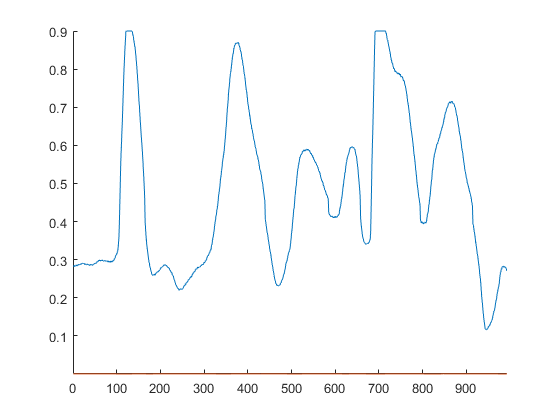


%  Visualize errors

figure
hold on
plot(yt)
plot(yhat)
hold off
axis([0 inf -inf inf])

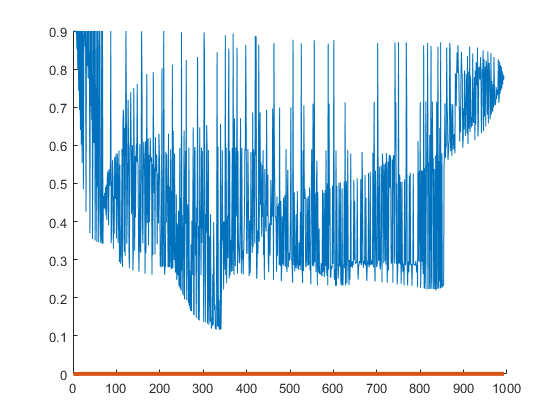


[sortout,Iss]=sort(yhat);
figure
hold on
plot(yt(Iss))
plot(sortout,'Linewidth',3)
hold off

Simulation Test data

[simoutput] = simnarx(TN,tinput,toutput,inlags,outlags,n,m);

fig = figure

fig =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


hold on
plot(10*toutput+1,'linewidth',2)
plot(10*simoutput+1,'linewidth',2)
hold off
beginz = max(outlags(end),inlags(end)) +1;
RMSE_St = sqrt(immse(10*toutput(beginz:end),10*simoutput(beginz:end)))

RMSE_St = 5.2245

toc

Elapsed time is 30.184089 seconds.


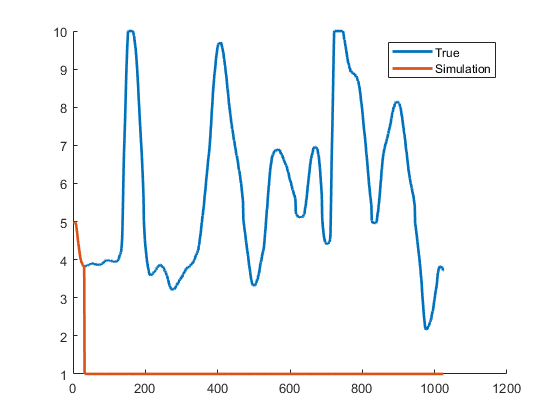

legend('True', 'Simulation')



% T = get(gca,'tightinset');
% set(gca,'position',[T(1) T(2) 1-T(1)-T(3) 1-T(2)-T(4)]);
% print(fig,'MySavedFile','-depsc')



Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %compression ratio

Compression: 4.0419e-16
